# Modified Heads and Legs Problem

If there are $S=100$ creatures from two different species in a dark room, and we take $s=20$ creatures randomly from the room. After that, we take $c=10$ animals from the $s=20$ creatures again, and denote the number of total legs of those $c$ creatures as $x$. 

**Question:** If we only have a list of $x$, how many individuals are there of species A and species B in $S$? How many legs ($a_1$ , $a_2$) does each species have?

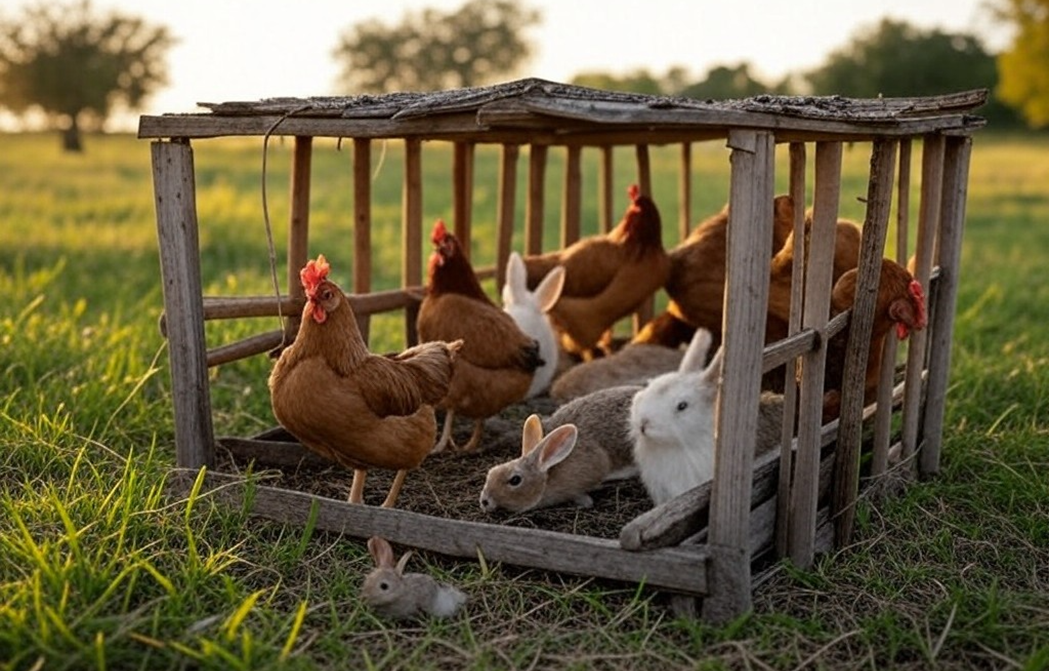           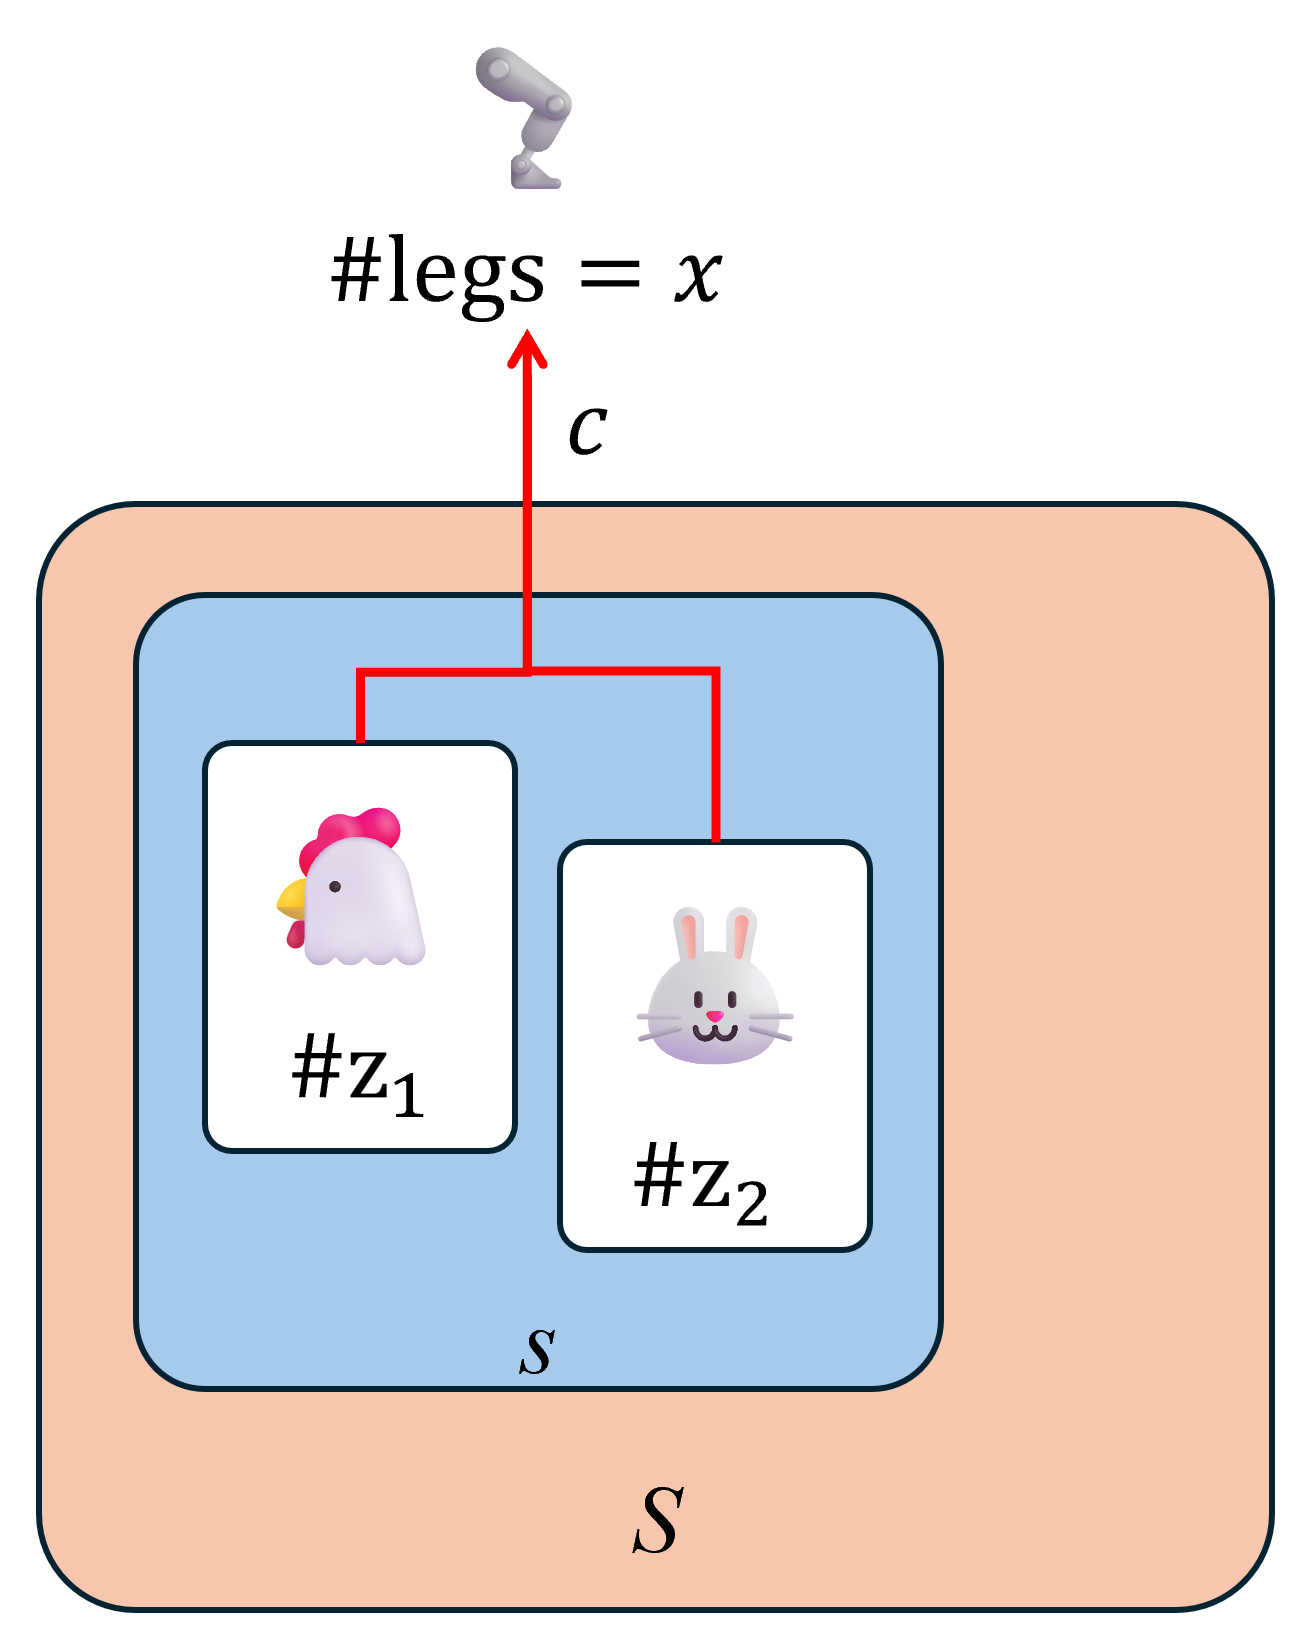

#### 1. Simulation of the task

Define the parameters in the task

S = 100;              % Total number of animals
nbz1 = 50;            % Total number of animal A
nbz2 = S - nbz1;      % Total number of animal B
s = 20;               % Number of animals being taken out from S
c = 10;               % Number of animals being taken out again from c

% Ground truth (used only for simulation, not for estimation)
true_a1 = 1;          % Legs for animal A
true_a2 = 6;          % Legs for animal B
true_pz1 = nbz1 / S;  % Convert number to probability
true_pz2 = nbz2 / S;  % Convert number to probability

N = 1000;    % Number of trials, dim of X

Simulated observations of Legs $x$, which is the only observable variable in the question.

x_samples = zeros(N, 1);   % Initialise Total legs in each trial

for trial = 1:N
    z1 = randi([0, c]);             % Number of animal A chosen
    z2 = c - z1;                    % Number of animal B chosen
    % Calculate sum of legs (Adding noise to simulate second sampling process):
    x_samples(trial) = ((z1 + randn(1)) * true_a1 + (z2 + randn(1)) * true_a2);   
end

figure(1),
histogram(x_samples, 100);           % Draw the histogarm of X
title('Histogram of X');
xlim([-5,80])

xlim([-9.1 75.9])
ylim([2.1 27.1])
 
x_samplesHistogram = findobj(gcf, "DisplayName", "x_samples")

x_samplesHistogram =   Histogram with properties:

             Data: [1000×1 double]
           Values: [1 2 1 1 1 3 2 4 6 3 3 5 5 11 6 8 17 1 13 7 9 14 5 12 12 19 26 11 11 13 12 15 14 11 9 14 11 17 16 14 7 17 22 15 11 9 13 21 13 11 12 24 13 17 7 15 20 14 20 16 12 13 11 15 11 18 11 21 18 8 17 17 14 17 7 5 14 9 10 12 10 … ] (1×100 double)
          NumBins: 100
         BinEdges: [-2.8000 -2.0150 -1.2300 -0.4450 0.3400 1.1250 1.9100 2.6950 3.4800 4.2650 5.0500 5.8350 6.6200 7.4050 8.1900 8.9750 9.7600 10.5450 11.3300 12.1150 12.9000 13.6850 14.4700 15.2550 16.0400 16.8250 17.6100 18.3950 … ] (1×101 double)
         BinWidth: 0.7850
        BinLimits: [-2.8000 75.7000]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show 

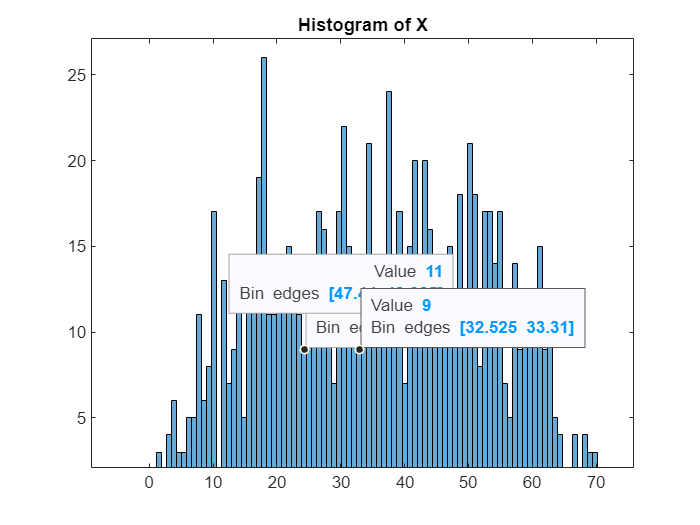

datatip(x_samplesHistogram,24.67,12);
datatip(x_samplesHistogram,47.91,13);
datatip(x_samplesHistogram,32.97,8);

#### 2. Problem formalisation 

Based on the Central Limit Theorem (CLT), we can use the following probabilities to trial results.

$x|z~\mathcal{N}\;\left(x|c\cdot a,I\right)$,

where $I$ is the covariance, $a$ is the number of legs each creature has and $z$ is the categorical indicator. Thus, the prior are:


$$P\left(z_1 \right)=\frac{{\textrm{#z}}_1 }{c},\;$$

$$P\left(z_2 \right)=\frac{{\textrm{#z}}_2 }{c}$$
 

The PDF of $x$ can be given as a mixture of 2 Gaussians.


$$p\left(x\right)=\sum_{k=1}^2 P\left(z_k \right)p\left(x|z_k \right)=P\left(z_1 \right)\mathcal{N}\;\left(x|{c\cdot a}_1 ,I\right)+P\left(z_2 \right)\mathcal{N}\;\left(x|{c\cdot a}_2 ,I\right)$$


#### 3. Expectation Maximization (EM)

The EM can estimate the proportion of two types of animals in $S$, and the legs $a_1$ , $a_2$ each species has.

**3.1 EM algorithm initialization**

pz1 = 0.4;              % Initialise animal A proportion
pz2 = 0.6;              % Initialise animal B proportion (p1 + p2 = 1)
legs1 = 1;              % Initialise legs of animal A
legs2 = 10;             % Initialise legs of animal B
Sigma = 10;             % Set the variance as a fixed value in this task

max_iterations = 100;   % Max number of iterations
tolerance = 1e-10;      % Convergence tolerance

EM loop

figure(2),
for iter = 1:max_iterations
        z1_expected = zeros(N, 1);  % Initialise expected animal A counts
        z2_expected = zeros(N, 1);  % Initialise expected animal B counts

**3.2 Expectation step** - Calculate posterior probabilities for each trial


$$p\left(z_{k\;} |x\right)=\frac{\textrm{likelihood}*\textrm{prior}}{\textrm{evidence}}=\frac{p\left(x|z\right)p\left(z\right)}{p\left(x\right)}=\frac{P\left(z_k \right)\mathcal{N}\;\left(x|c\cdot a_{k\;} ,I\right)}{P\left(z_1 \right)\mathcal{N}\;\left(x|{c\cdot a}_1 ,I\right)+P\left(z_2 \right)\mathcal{N}\;\left(x|{c\cdot a}_2 ,I\right)}$$


    for trial = 1:N
        % Calculate likelihood for animal A and animal B
        likelihood_type1 = normpdf(x_samples(trial), c * legs1, Sigma);
        likelihood_type2 = normpdf(x_samples(trial), c * legs2, Sigma);
        
        % Posterior probabilities
        evidence = pz1 * likelihood_type1 + pz2 * likelihood_type2;
        z1_expected(trial) = (pz1 * likelihood_type1) / evidence;
        z2_expected(trial) = (pz2 * likelihood_type2) / evidence;
    end

**3.3 Maximization step** - Update parameters


$$\mu_k =\frac{\sum_{n=1}^N p\left(z_k |x_n \right){\cdot x}_n }{\sum_{n=1}^N p\left(z_k |x_n \right)}$$


    pz1_new = mean(z1_expected);
    pz2_new = mean(z2_expected);
    legs1_new = sum(z1_expected .* x_samples) / (c * sum(z1_expected));
    legs2_new = sum(z2_expected .* x_samples) / (c * sum(z2_expected));

Loop control - Check convergence

    if abs(pz1_new - pz1) < tolerance && abs(legs1_new - legs1) < tolerance && ...
       abs(pz2_new - pz2) < tolerance && abs(legs2_new - legs2) < tolerance
        break;
    end

    % Update parameters for the next iteration
    pz1 = pz1_new;
    pz2 = pz2_new;
    legs1 = legs1_new;
    legs2 = legs2_new;

Darw the updated PDF after each iteration

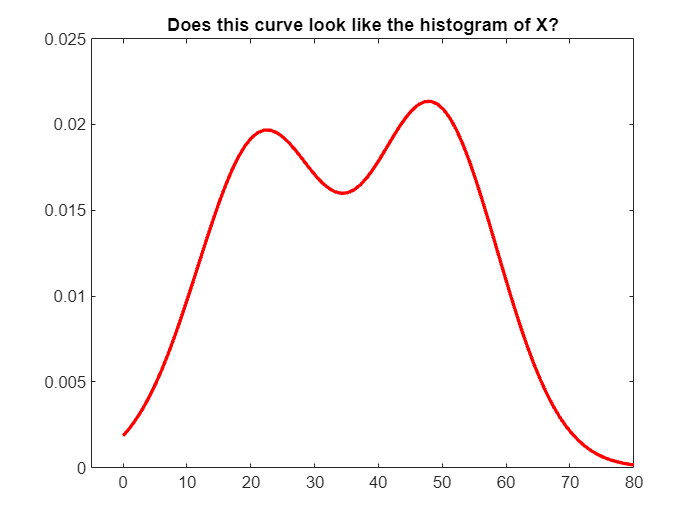

    plot_gmm_curve(c*legs1, c*legs2, pz1, pz2, Sigma);
    title('Does this curve look like the histogram of X?')
    xlim([-5,80])
    pause(0.1)
end

Display estimated results from the EM

fprintf('Estimated proportion of animal A: %.4f\n', pz1);

Estimated proportion of animal A: 0.4782


fprintf('Estimated proportion of animal B: %.4f\n', pz2);

Estimated proportion of animal B: 0.5218


fprintf('Estimated legs of animal A: %.4f\n', legs1);

Estimated legs of animal A: 2.1599


fprintf('Estimated legs of animal B: %.4f\n', legs2);

Estimated legs of animal B: 4.8620


**Function for plotting the GMM**

function plot_gmm_curve(mu1,mu2,p1,p2,I)
    x = linspace(0, 200, 200);
    y1 = normpdf(x, mu1, I); 
    y2 = normpdf(x, mu2, I); 
    y = p1 * y1 + p2 * y2;
    plot(x, y, 'r', 'LineWidth', 2);
end